802.11ac SEM

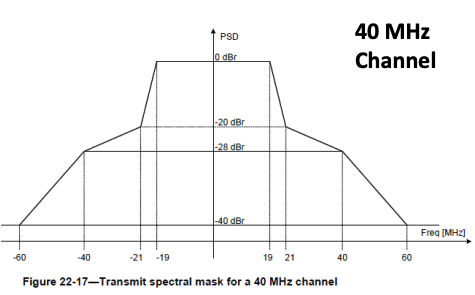

function SEM = ac(delta_f, f_range, B)
    % Generate only the positive part
    f = f_range(1):delta_f:f_range(2);
    SEM = zeros(length(f), 1);
        
    for idx = 1:length(f)
        if f(idx) < 19/B
            % freq: 0~19 MHz
            SEM(idx) = 0;
        elseif f(idx) < 21/B
            % freq: 19~21 MHz
            SEM(idx) = -10 * (f(idx)*B - 19);
        elseif f(idx) < 40/B
            % freq: 21~40 MHz
            SEM(idx) = -20 -0.4211 * (f(idx)*B - 21);
        elseif f(idx) < 60/B
            % freq: 40~60 MHz
            SEM(idx) = -28 -0.6 * (f(idx)*B - 40);
        else
            % freq: >60 MHz
            SEM(idx) = -40;
        end
    end
    
     % Generate the negative part
     SEM = [flipud(SEM); SEM(2:end)];
end